clearvars -except xxkg hkg k xxkg2 hkg2
% % % 
in = xxkg(k);
ReFs = 20;
heat = 8;
channel = 1;
x1 = 175;
x2 = 225;

%% crop data to temptimes
%define variables
temptims = sort([in.info.temptims]);
poweridx = [in.info.poweridx];
%prepare data variables

%outlier removal
 tto = [in.idx(channel).obwidx]; 
      
%raw data
    timcont = [in.e(channel).s(tto).timcont]; %time in seconds
    obw = [in.e(channel).s(tto).obwAmp]/max([in.e(channel).s(tto).obwAmp]); %divide by max to normalize
    temp =  [in.e(channel).s(tto).temp];
    freq =  [in.e(channel).s(tto).fftFreq];

%Take top of dataset
    %find peaks
    [freqpeak1,LOCS] = findpeaks(freq);
    freqtim1 = timcont(LOCS);
    %find peaks of the peaks
    [freqpeak2,cLOCS] = findpeaks(freq(LOCS));
    freqtim2 = timcont(LOCS(cLOCS));

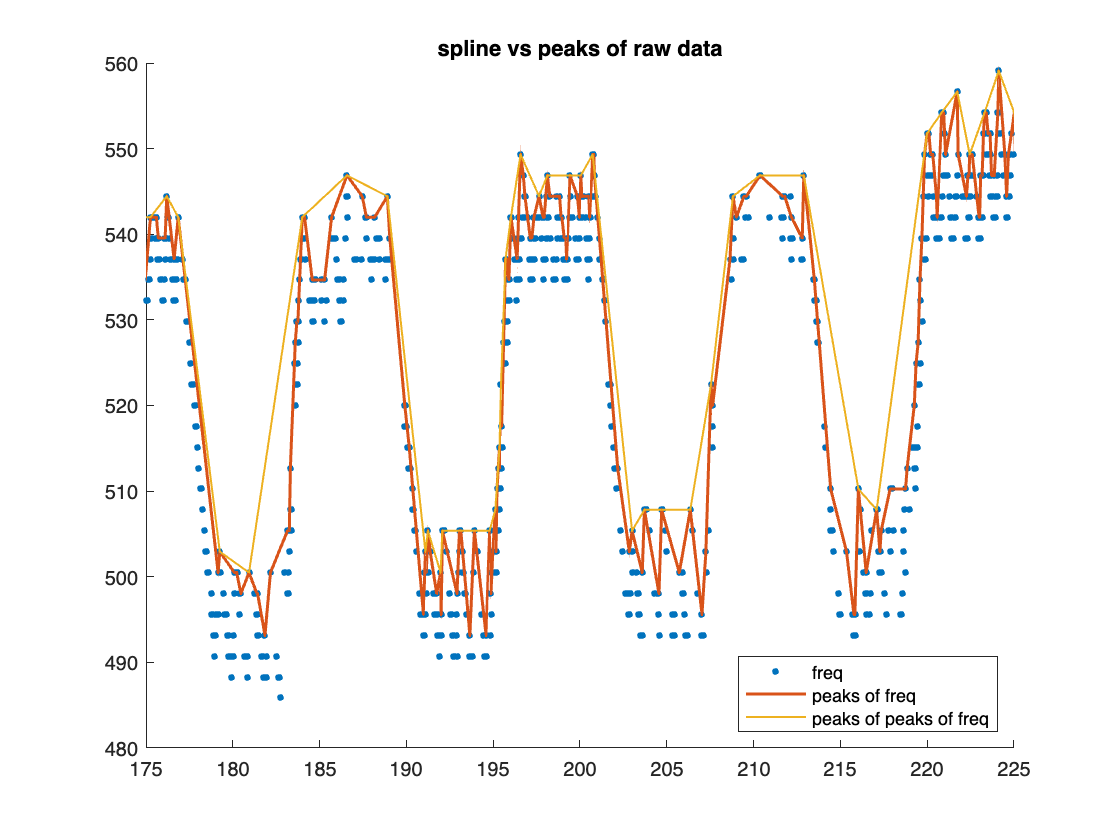

figure(62); clf; title('spline vs peaks of raw data'); ylim = ([0,.8]); hold on; xlim([x1, x2]); 
  
       
        plot(timcont/3600, freq, '.', 'MarkerSize', 10, 'DisplayName','freq');
        plot(freqtim1/3600, freqpeak1,  'DisplayName','peaks of freq', 'LineWidth', 1.5);
        plot(freqtim2/3600, freqpeak2,  'MarkerSize', 10, 'DisplayName','peaks of peaks of freq', 'LineWidth', 1);
legend('Location', 'southeast' );

 %regularize data to ReFs interval
    [regfreqtim, regfreqpeaks] = k_regularmetamucil(freqtim1, freqpeak1, timcont, oldfreq, ReFs, temptims);